# Wine Quality - Reducing Predictors

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code loads and displays the wine data and a trained 7-fold cross-validated quadratic DA model of `redData`.

rng(0)
redData = readtable("data\redWine.csv")

redData = 1593×12 table
    FixedAcidity    VolatileAcidity    CitricAcid    ResidualSugar    Chlorides    FreeSulfurDioxide    TotalSulfurDioxide    Density      pH      Sulphates    Alcohol    QCLabel
    ____________    _______________    __________    _____________    _________    _________________    __________________    _______    ______    _________    _______    _______

       0.2478           0.3973               0          0.0685         0.1068           0.1408                0.0989          0.5675     0.6063     0.1377      0.1538      {'D'} 
       0.2832           0.5205

redData.QCLabel = categorical(redData.QCLabel);
cvpt = cvpartition(redData.QCLabel, "KFold", 7);
mdlFull = fitcdiscr(redData, "QCLabel", "CVPartition", cvpt);
fullLoss = kfoldLoss(mdlFull)

fullLoss = 0.4105

## Reduce Predictors

The table `redData` contains several features of red wine and the corresponding quality, which is saved in the `QCLabel` variable.

Fit model with fewer predictors. Target loss value less than 0.45.

**Method: Feature Selection (Tree)**

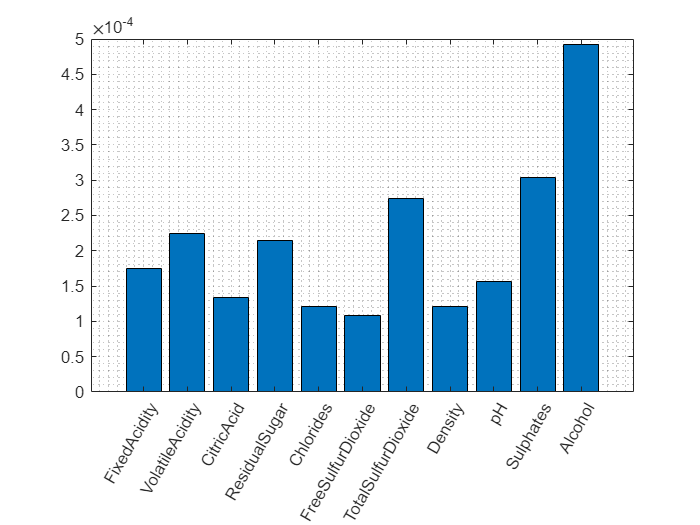

tModel = fitctree(redData, "QCLabel");
p = predictorImportance(tModel);

% View predictor importance on a bar plot
bar(p)
grid minor
xticklabels(redData.Properties.VariableNames(1:end-1))
xtickangle(60)


% Sort out the top predictors
[~, iSorted] = sort(p);
selected = [iSorted(1:6) width(redData)];

% Create tree model to reduced data
mdl = fitctree(redData(:, selected), "QCLabel", "KFold", 7);
mdlLoss = kfoldLoss(mdl)

mdlLoss = 0.4576

**Method: Feature Transformation (PCA)**

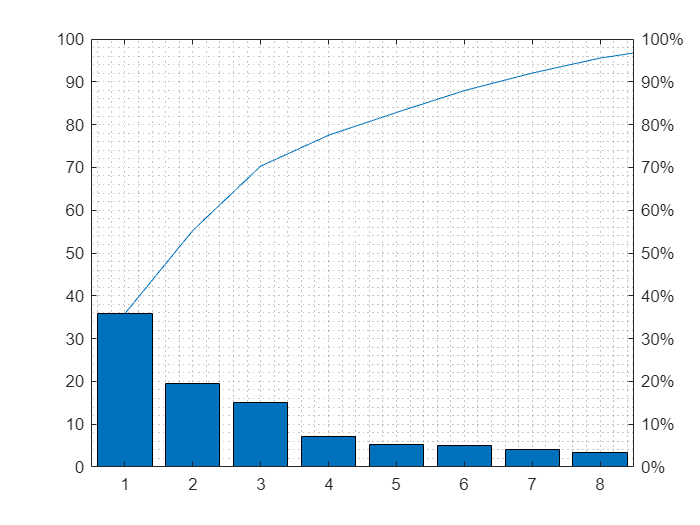

[pcs, scrs, ~, ~, pexp] = pca(redData{:, 1:end-1});
pareto(pexp)
grid minor


% Create k-NN model to reduced data
mdl = fitcknn(scrs(:, 1:3), redData.QCLabel, "KFold", 7);
mdlLoss = kfoldLoss(mdl)

mdlLoss = 0.3810